close all;
clear;
clc;

m = 1.535; %mass of drone
g = 9.81; %gravity

%Inertia values
Ixx= 0.029125;
Iyy= 0.029125;
Izz= 0.055225; 

%Drag constants
kt=0.0;
kr=0.0;

%Variables initalisation
phi=0.0;
theta=0.0;
psi=0.0;

x_dot=0.0;
y_dot=0.0;
z_dot=0.0;

x=0.0;
y=0.0;
z=0.0;


%velocity desired values
x_dot_d=0.0;
y_dot_d=0.0;
z_dot_d=0.0;

%Position desired value
x_d=1.0;
y_d=2.0;
z_d=5.0;

theta_d=0.0;
phi_d=0.0;
psi_d=0.0;


% Time period of controller(50 ms)
dt = 0.01;
t_total = 50;
tspan = 0:dt:t_total; % Full time range

y0 = zeros(12, 1); % Initial state

u = [0; 0.0; 0.0; 0.0]; % Initial control input
y_all = []; % To store all states
t_all = []; % To store all time
current_state = y0; % Start with the initial state
T=0;



%PID gains for attitude controller

%Zeta =1 , critically damped system
Ts_phi=0.1;
kd_phi=8*Iyy/Ts_phi;
kp_phi=(kd_phi*kd_phi)/(4*Ixx*3*3);
ki_phi=0.0;

Ts_theta=0.1;
kd_theta=8*Iyy/Ts_theta;
kp_theta=(kd_theta*kd_theta)/(4*Iyy*3*3);
ki_theta=0.0;

Ts_psi=0.1;
kd_psi=8*Izz/Ts_psi;
kp_psi=(kd_psi*kd_psi)/(4*Izz);
ki_psi=0.0;

% PID GAINS for Velocity Controller

Ts_z_dot= 1.0;
kd_z_dot=0.465;
kp_z_dot= 4*(m+kd_z_dot)/Ts_z_dot;
ki_z_dot=0.0;

Ts_x_dot= 1.0;
kd_x_dot= 0.01;
kp_x_dot= (1.0981*4)/(9.81*Ts_x_dot);
ki_x_dot=0.0;

Ts_y_dot= 1.0;
kd_y_dot= 0.01;
kp_y_dot= (1.0981*4)/(9.81*Ts_y_dot);
ki_y_dot=0.0;

%P Controller gains for positions
kp_x=0.4;
kp_y=0.4;
kp_z=0.4;

%Temp variables
error_prev_z_dot=0.0;
error_prev_z_dot_in=0.0;

error_prev_x_dot=0.0;
error_prev_x_dot_in=0.0;

error_prev_y_dot=0.0;
error_prev_y_dot_in=0.0;

error_prev_theta=0.0;
error_prev_theta_in=0.0;

error_prev_phi=0.0;
error_prev_phi_in=0.0;

error_prev_psi=0.0;
error_prev_psi_in=0.0;


%Motor Thrust
% T1=0;
% T2=0;
% T3=0;
% T4=0;
% TM=[T1;T2;T3;T4];
% 
% %Control Allocation Matrix
% c=0.1;
% l=0.1;
% CM = [1 1 1 1; 0 -l 0 l;-l 0 l 0; c -c c -c];

for i = 1:length(tspan)-1

    t_current = [tspan(i), tspan(i+1)];

    %Altitude height

    %P CONTROL for position
    z_dot_d=kp_z*(z_d-z);
    z_dot_d=min(15,z_dot_d);
    %PID CONTROL for z velocity
    [u(1),error_prev_z_dot,error_prev_z_dot_in]=pid_control(z_dot,z_dot_d,error_prev_z_dot,error_prev_z_dot_in,kp_z_dot,ki_z_dot,kd_z_dot,dt);
    u(1)=(u(1)+m*g);
    

    %Attitude theta

    %P CONTROL for x position
    x_dot_d=kp_x*(x_d-x);
    x_dot_d=min(8.5,x_dot_d);

    %PID CONTROL for x velocity 
    [theta_d,error_prev_x_dot,error_prev_x_dot_in]=pid_control(x_dot,x_dot_d,error_prev_x_dot,error_prev_x_dot_in,kp_x_dot,ki_x_dot,kd_x_dot,dt);
    if (theta_d>0.0)   
    theta_d=min(0.17,theta_d);
    end
    if (theta_d<0.0)   
    theta_d=max(-0.17,theta_d);
    end
    [u(3),error_prev_theta,error_prev_theta_in]=pid_control(theta,theta_d,error_prev_theta,error_prev_theta_in,kp_theta,ki_theta,kd_theta,dt);

    
    %Attitude phi
    
    %P CONTROL for y position
    y_dot_d=kp_y*(y_d-y);
    y_dot_d=min(8.5,y_dot_d);

    %PID CONTROL for y velocity 
    [phi_d,error_prev_y_dot,error_prev_y_dot_in]=pid_control(y_dot,y_dot_d,error_prev_y_dot,error_prev_y_dot_in,kp_y_dot,ki_y_dot,kd_y_dot,dt);
    if (phi_d>0.0)   
    phi_d=min(0.17,phi_d);
    end
    if (phi_d<0.0)   
    phi_d=max(-0.17,phi_d);
    end
    [u(2),error_prev_phi,error_prev_phi_in]=pid_control(phi,-phi_d,error_prev_phi,error_prev_phi_in,kp_phi,ki_phi,kd_phi,dt);
    
    %Attitude yaw PID control
    [u(4),error_prev_psi,error_prev_psi_in]=pid_control(psi,psi_d,error_prev_psi,error_prev_psi_in,kp_psi,ki_psi,kd_psi,dt);

    [t, y] = ode45(@(t, y) droneDynamics(t, y, u,m,g,Ixx,Iyy,Izz,kt,kr), t_current, current_state);
    y_all = [y_all; y(1:end-1, :)]; % Exclude the last point to avoid duplication
    t_all = [t_all; t(1:end-1)];
    
    % Update the current state
    current_state = y(end, :)';

    phi=current_state(7);
    theta=current_state(8);
    psi=current_state(9);
    
       x_dot=current_state(4);
    y_dot=current_state(5);
    z_dot=current_state(6);

    x=current_state(1);
    y=current_state(2);
    z=current_state(3);

end

% Add the final point
y_all = [y_all; current_state'];
t_all = [t_all; tspan(end)];

x=current_state(1)

x = 1.0000

y=current_state(2)

y = 2.0000

z=current_state(3)

z = 5.0000


x_dot=current_state(4)

x_dot = 1.0281e-10

y_dot=current_state(5)

y_dot = 2.0997e-10

z_dot=current_state(6)

z_dot = 7.6168e-10


phi=current_state(7)

phi = 9.5408e-12

theta=current_state(8)

theta = -4.6714e-12

psi=current_state(9)

psi = -1.1496e-26

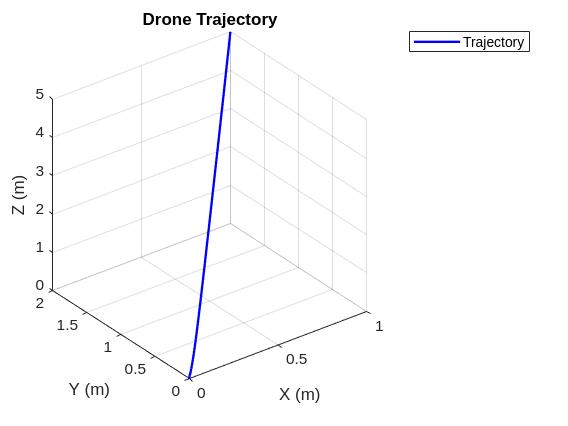


% Plot Drone Trajectory
figure;
plot3(y_all(:, 1), y_all(:, 2), y_all(:, 3), 'b', 'LineWidth', 1.5);
grid on;
xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
title('Drone Trajectory');
legend('Trajectory');

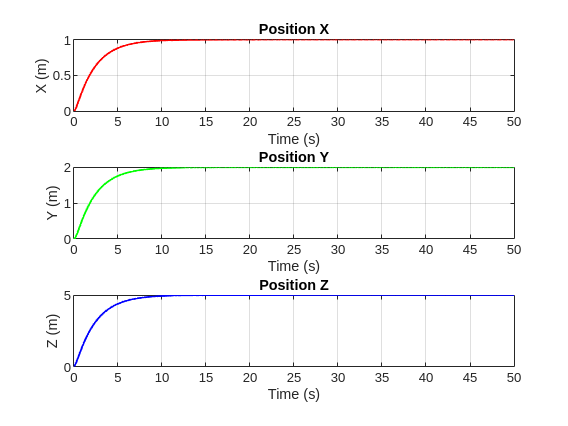


% Plot Position over Time
figure;
subplot(3, 1, 1);
plot(t_all, y_all(:, 1), 'r', 'LineWidth', 1.2);
grid on;
xlabel('Time (s)'); ylabel('X (m)');
title('Position X');

subplot(3, 1, 2);
plot(t_all, y_all(:, 2), 'g', 'LineWidth', 1.2);
grid on;
xlabel('Time (s)'); ylabel('Y (m)');
title('Position Y');

subplot(3, 1, 3);
plot(t_all, y_all(:, 3), 'b', 'LineWidth', 1.2);
grid on;
xlabel('Time (s)'); ylabel('Z (m)');
title('Position Z');

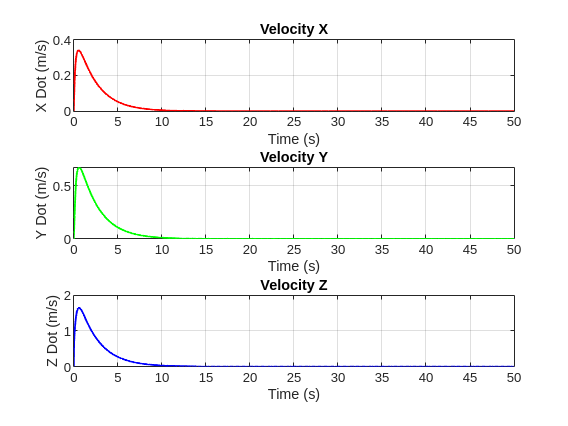


% Plot Velocities
figure;
subplot(3, 1, 1);
plot(t_all, y_all(:, 4), 'r', 'LineWidth', 1.2);
grid on;
xlabel('Time (s)'); ylabel('X Dot (m/s)');
title('Velocity X');

subplot(3, 1, 2);
plot(t_all, y_all(:, 5), 'g', 'LineWidth', 1.2);
grid on;
xlabel('Time (s)'); ylabel('Y Dot (m/s)');
title('Velocity Y');

subplot(3, 1, 3);
plot(t_all, y_all(:, 6), 'b', 'LineWidth', 1.2);
grid on;
xlabel('Time (s)'); ylabel('Z Dot (m/s)');
title('Velocity Z');

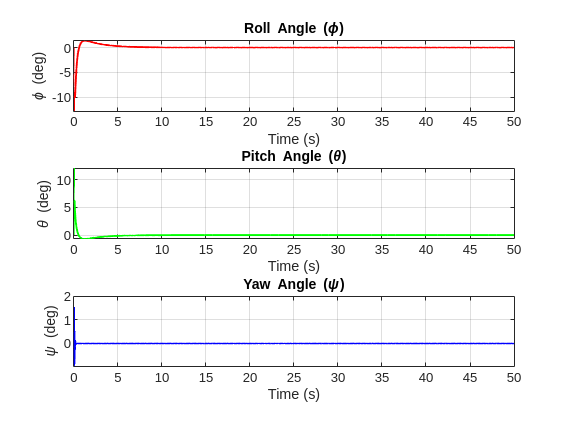


% Plot Orientation Angles
figure;
subplot(3, 1, 1);
plot(t_all, rad2deg(y_all(:, 7)), 'r', 'LineWidth', 1.2);
grid on;
xlabel('Time (s)'); ylabel('\phi (deg)');
title('Roll Angle (\phi)');

subplot(3, 1, 2);
plot(t_all, rad2deg(y_all(:, 8)), 'g', 'LineWidth', 1.2);
grid on;
xlabel('Time (s)'); ylabel('\theta (deg)');
title('Pitch Angle (\theta)');

subplot(3, 1, 3);
plot(t_all, rad2deg(y_all(:, 9)), 'b', 'LineWidth', 1.2);
grid on;
xlabel('Time (s)'); ylabel('\psi (deg)');
title('Yaw Angle (\psi)');